% Celal AKSOY

# **Flexible Satellite Attitude Control**

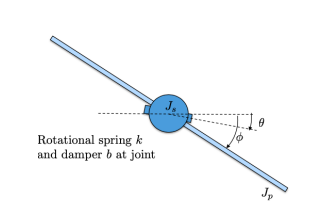

## **Equation of Motion of the Satellite**

syms s js jp theta(t) fi(t) b k Tork

Eom1 = js*diff(theta(t),t,2)+b*(diff(theta(t),t,1)-diff(fi,t,1))+k*(theta(t)-fi(t)) == Tork;
disp(Eom1)

$$\mathrm{js}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-b\,\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right)\right)-k\,\left(\mathrm{fi}\left(t\right)-\theta \left(t\right)\right)=\mathrm{Tork}$$

Eom2 = jp*diff(fi(t),t,2)+b*(diff(fi,t,1)-diff(theta(t),t,1))+k*(fi(t)-theta(t)) == 0;
disp(Eom2)      

$$k\,\left(\mathrm{fi}\left(t\right)-\theta \left(t\right)\right)+\mathrm{jp}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)+b\,\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right)\right)=0$$

Since the obtained equation is already linear, linearization was not required.

## **Laplace Transformation**

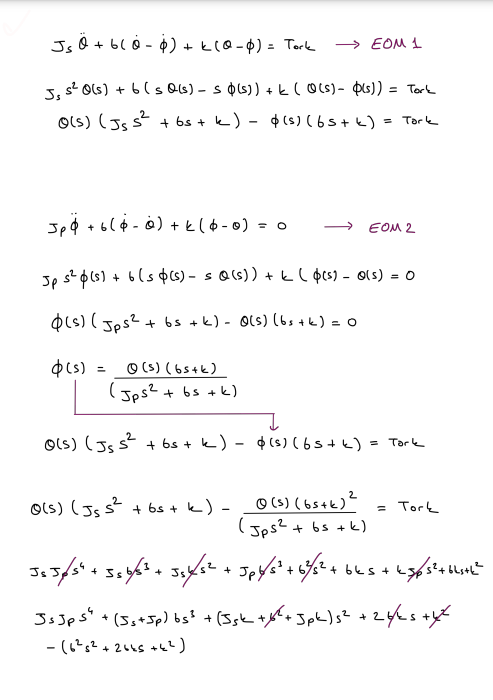

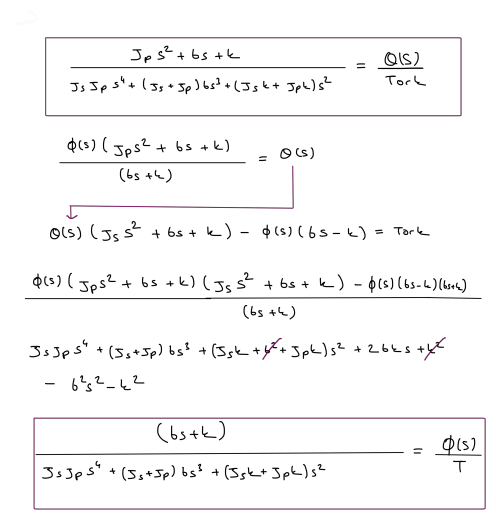

## ** Transfer Functions**

Js = 5;        % kg*m^2
Jp = 1;        % kg*m^2
k = 0.15;      % N*m
b = 0.05;      % N*m*s

num1 = [Jp b k];
den1 = [Js*Jp (Js+Jp)*b (Js+Jp)*k 0 0];
Gtheta = tf(num1,den1)

Gtheta =
 
     s^2 + 0.05 s + 0.15
  -------------------------
  5 s^4 + 0.3 s^3 + 0.9 s^2
 
Continuous-time transfer function.



num2 = [b k];
den2 = [Js*Jp (Js+Jp)*b (Js+Jp)*k 0 0];
Gfi = tf(num2,den2)

Gfi =
 
        0.05 s + 0.15
  -------------------------
  5 s^4 + 0.3 s^3 + 0.9 s^2
 
Continuous-time transfer function.



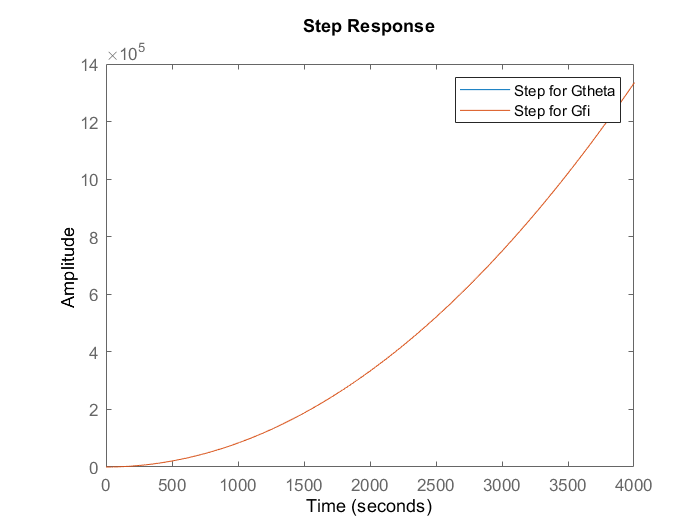

figure
step(Gtheta);
hold on
step(Gfi);
legend('Step for Gtheta','Step for Gfi');
hold off

## **State Space Representation**

A1 = [0 0 1 0; 0 0 0 1; -k/Js k/Js -b/Js b/Js; k/Jp -k/Jp b/Jp -b/Jp];
B1 = [0; 0; 1/Js; 0];
C1 = [1 0 0 0];
D1 = [0];

SStheta = ss(A1,B1,C1,D1)

SStheta =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3  -0.03   0.03  -0.01   0.01
   x4   0.15  -0.15   0.05  -0.05
 
  B = 
        u1
   x1    0
   x2    0
   x3  0.2
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



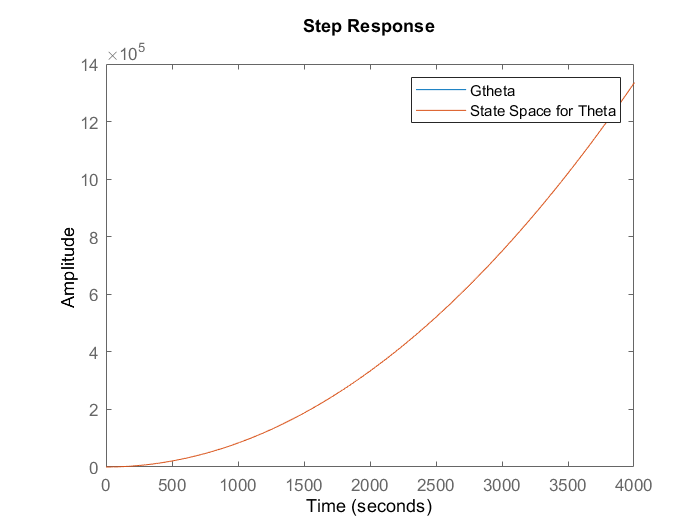

figure
step(Gtheta);
hold on
step(SStheta)
legend('Gtheta','State Space for Theta')
hold off

A2 = [0 0 1 0; 0 0 0 1; -k/Js k/Js -b/Js b/Js; k/Jp -k/Jp b/Jp -b/Jp];
B2 = [0; 0; 1/Js; 0];
C2 = [0 1 0 0];
D2 = [0];

SSfi = ss(A2,B2,C2,D2)

SSfi =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3  -0.03   0.03  -0.01   0.01
   x4   0.15  -0.15   0.05  -0.05
 
  B = 
        u1
   x1    0
   x2    0
   x3  0.2
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



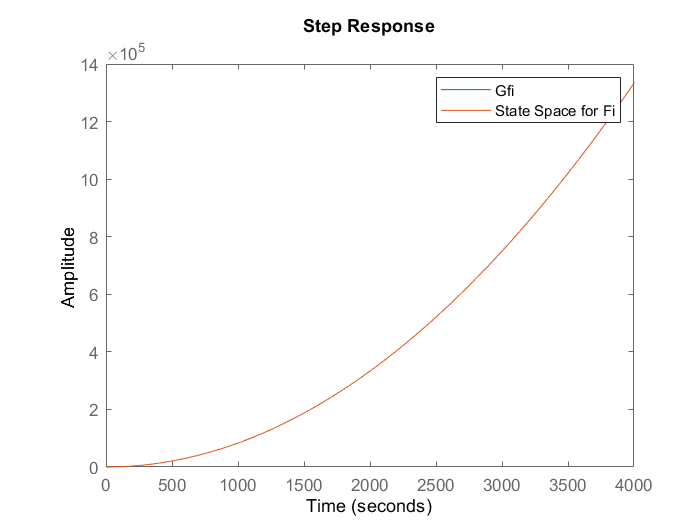

figure
step(Gfi);
hold on
step(SSfi)
legend('Gfi','State Space for Fi')
hold off

##  **PID Controller**

kc = margin(Gtheta)

kc = 0

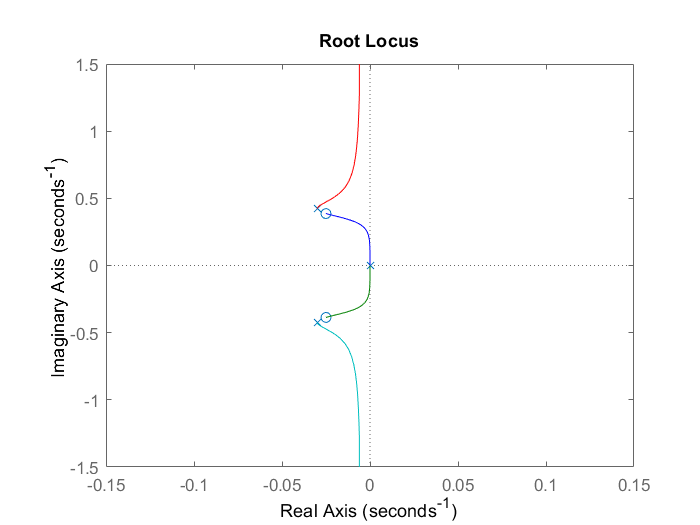

rlocus(Gtheta)

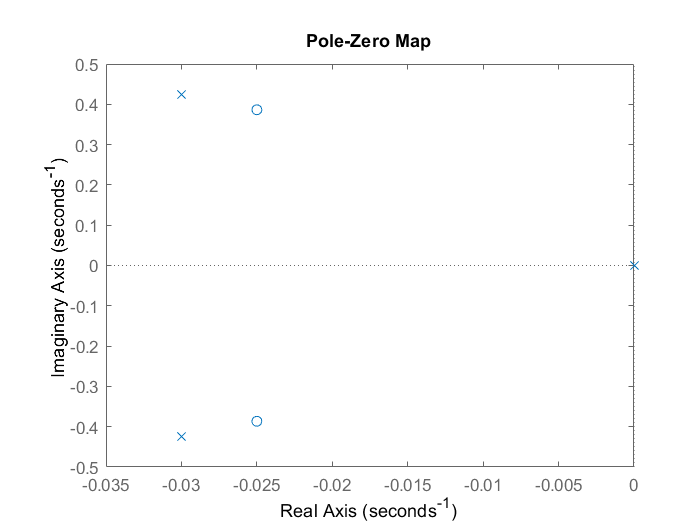

pzmap(Gtheta)

zpk(Gtheta)

ans =
 
  0.2 (s^2 + 0.05s + 0.15)
  ------------------------
  s^2 (s^2 + 0.06s + 0.18)
 
Continuous-time zero/pole/gain model.



kc1 = margin(Gfi)

kc1 = 0

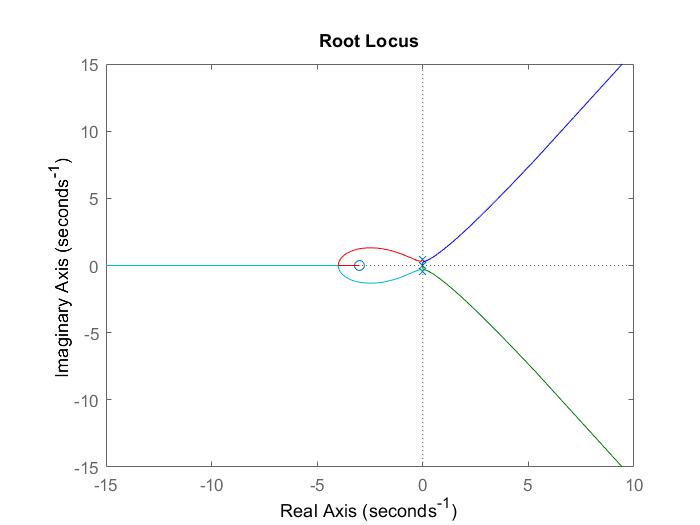

rlocus(Gfi)

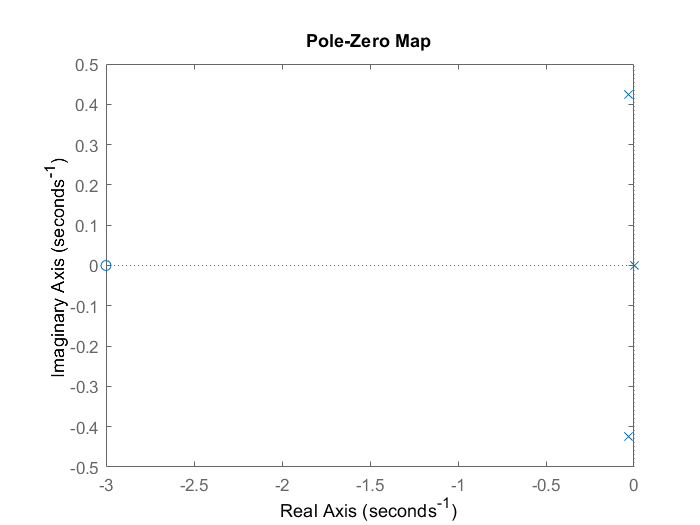

pzmap(Gfi)

zpk(Gfi)

ans =
 
         0.01 (s+3)
  ------------------------
  s^2 (s^2 + 0.06s + 0.18)
 
Continuous-time zero/pole/gain model.



## **PD Controller**

syms s kd p11 p21 kp real  

Gfisyms = (0.01*(s+3))/((s^2)*(s^2+0.06*s+0.18)); 

PD = kp+kd*s

$$PD = \mathrm{kp}+\mathrm{kd}\,s$$

Overshoot1 = 0.05; 
zeta1 = -log(Overshoot1)/sqrt(pi^2+log(Overshoot1)^2)

zeta1 = 0.6901

SettlingTime1 = 3;
Sigma1 = 4 /SettlingTime1;
wn1 = Sigma1/zeta1

wn1 = 1.9321

Tfde = (s^2+2*wn1*zeta1*s+wn1^2)*(s+p11)*(s+p21);
Tfcpd=simplify(PD*Gfisyms/(1+PD*Gfisyms))

$$Tfcpd = \frac{\left(\mathrm{kp}+\mathrm{kd}\,s\right)\,\left(s+3\right)}{3\,\mathrm{kp}+3\,\mathrm{kd}\,s+\mathrm{kp}\,s+\mathrm{kd}\,s^{2}+18\,s^{2}+6\,s^{3}+100\,s^{4}}$$

[n4,d4]=numden(Tfcpd);
n4=coeffs(n4,s,'all');
d4= coeffs(d4,s,'all');
d4=d4/d4(1)

$$d4 = \left(\begin{array}{ccccc} 1 & \frac{3}{50} & \frac{\mathrm{kd}}{100}+\frac{9}{50} & \frac{3\,\mathrm{kd}}{100}+\frac{\mathrm{kp}}{100} & \frac{3\,\mathrm{kp}}{100} \end{array}\right)$$

prob=d4==coeffs(Tfde,s,'all');
for i=1:length(prob)
disp(vpa( prob(i),4));
end

$$1.0=1.0$$

$$0.06=p_{11}+p_{21}+2.667$$

$$0.01\,\mathrm{kd}+0.18=2.667\,p_{11}+2.667\,p_{21}+p_{11}\,p_{21}+3.733$$

$$0.03\,\mathrm{kd}+0.01\,\mathrm{kp}=3.733\,p_{11}+3.733\,p_{21}+2.667\,p_{11}\,p_{21}$$

$$0.03\,\mathrm{kp}=3.733\,p_{11}\,p_{21}$$

PDsolution=solve(prob);
kp = double(PDsolution.kp)

kp =    36.6180
   36.6180


kd = double(PDsolution.kd)

kd =  -310.3937
 -310.3937


p11 = double(PDsolution.p11)

p11 =    -0.1183
   -2.4884


P21= double(PDsolution.p21)

P21 =    -2.4884
   -0.1183


s = tf('s');
Gfitf = (0.01*(s+3))/((s^2)*(s^2+0.06*s+0.18));
Pdtf = kp+kd*s;
Tfcpd1 = feedback(Gfitf*Pdtf(1),1)

Tfcpd1 =
 
          -3.104 s^2 - 8.946 s + 1.099
  --------------------------------------------
  s^4 + 0.06 s^3 - 2.924 s^2 - 8.946 s + 1.099
 
Continuous-time transfer function.



zpk(Tfcpd1)

ans =
 
            -3.1039 (s+3) (s-0.118)
  -------------------------------------------
  (s-2.488) (s-0.1183) (s^2 + 2.667s + 3.733)
 
Continuous-time zero/pole/gain model.



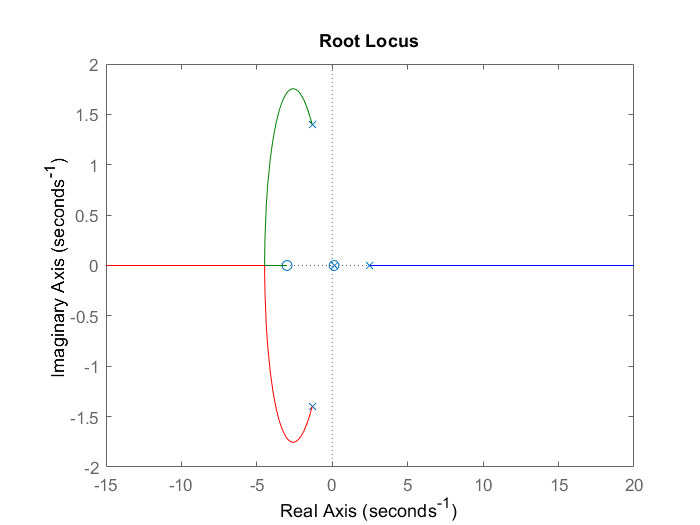

rlocus(Tfcpd1)

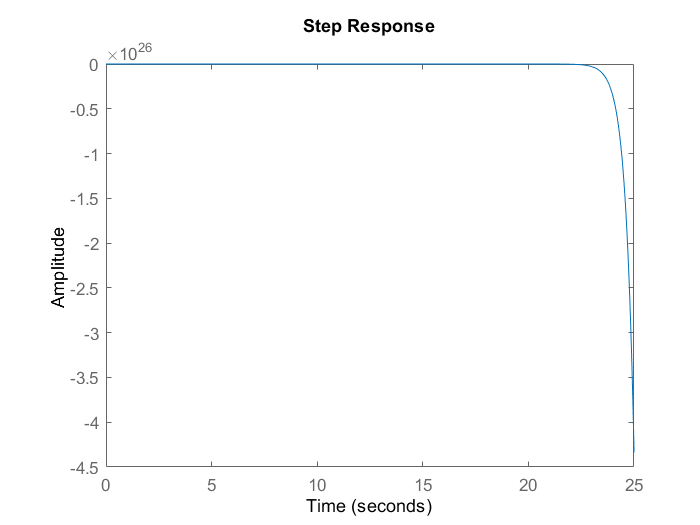

step(Tfcpd1)

## PI Controller

kcd = margin(Tfcpd1)

kcd = Inf

syms s ki p111 p211 p311 kp real

Gfisyms = (0.01*(s+3))/((s^2)*(s^2+0.06*s+0.18))

$$Gfisyms = \frac{\frac{s}{100}+\frac{3}{100}}{s^{2}\,\left(s^{2}+\frac{3\,s}{50}+\frac{9}{50}\right)}$$

PI = kp+ki/s

$$PI = \mathrm{kp}+\frac{\mathrm{ki}}{s}$$

Overshoot1 = 0.05;
zeta1 = -log(Overshoot1)/sqrt(pi^2+log(Overshoot1)^2)

zeta1 = 0.6901

SettlingTime1 = 3;
Sigma1 = 4 /SettlingTime1;
wn1 = Sigma1/zeta1

wn1 = 1.9321

Tfdepi = (s^2+2*wn1*zeta1*s+wn1^2)*(s+p111)*(s+p211)*(s+p311);
Tfcpd = simplify(PI*Gfisyms/(1+PI*Gfisyms))

$$Tfcpd = \frac{\left(\mathrm{ki}+\mathrm{kp}\,s\right)\,\left(s+3\right)}{3\,\mathrm{ki}+\mathrm{ki}\,s+3\,\mathrm{kp}\,s+\mathrm{kp}\,s^{2}+18\,s^{3}+6\,s^{4}+100\,s^{5}}$$

[n5, d5] = numden(Tfcpd);
n5 = coeffs(n5, s, 'all');
d5 = coeffs(d5, s, 'all');
d5 = d5 / d5(1);

prob2 = d5 == coeffs(Tfdepi, s, 'all');
for i = 1:length(prob2)
    disp(vpa(prob2(i), 4));
end

$$1.0=1.0$$

$$0.06=p_{111}+p_{211}+p_{311}+2.667$$

$$0.18=2.667\,p_{111}+2.667\,p_{211}+2.667\,p_{311}+p_{311}\,\left(p_{111}+p_{211}\right)+p_{111}\,p_{211}+3.733$$

$$0.01\,\mathrm{kp}=3.733\,p_{111}+3.733\,p_{211}+3.733\,p_{311}+2.667\,p_{311}\,\left(p_{111}+p_{211}\right)+2.667\,p_{111}\,p_{211}+p_{111}\,p_{211}\,p_{311}$$

$$0.01\,\mathrm{ki}+0.03\,\mathrm{kp}=3.733\,p_{311}\,\left(p_{111}+p_{211}\right)+3.733\,p_{111}\,p_{211}+2.667\,p_{111}\,p_{211}\,p_{311}$$

$$0.03\,\mathrm{ki}=3.733\,p_{111}\,p_{211}\,p_{311}$$

PDsolution2 = solve(prob2);
kp = double(PDsolution2.kp)


kp =

  0×1 empty double column vector



ki = double(PDsolution2.ki)


ki =

  0×1 empty double column vector



p111 = double(PDsolution2.p111)


p111 =

  0×1 empty double column vector



p211 = double(PDsolution2.p211)


p211 =

  0×1 empty double column vector



p311 = double(PDsolution2.p311)


p311 =

  0×1 empty double column vector



%s = tf('s');
%Gfitf = (0.01*(s+3))/((s^2)*(s^2+0.06*s+0.18));
%Pitf = kp+(ki/s);
%Tfcpi1 = feedback(Gfitf*Pitf, 1);

%zpk(Tfcpi1);
%rlocus(Tfcpi1);
%step(Tfcpi1);

## **PID TUNE**

PIDforGfi = pidtune(Gfi,'PID')

PIDforGfi =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000644, Ki = 8.08e-07, Kd = 0.128
 
Continuous-time PID controller in parallel form.



Gfiwithpid= feedback(PIDforGfi*Gfi,1)

Gfiwithpid =
 
          0.006408 s^3 + 0.01926 s^2 + 9.661e-05 s + 1.213e-07
  --------------------------------------------------------------------
  5 s^5 + 0.3 s^4 + 0.9064 s^3 + 0.01926 s^2 + 9.661e-05 s + 1.213e-07
 
Continuous-time transfer function.



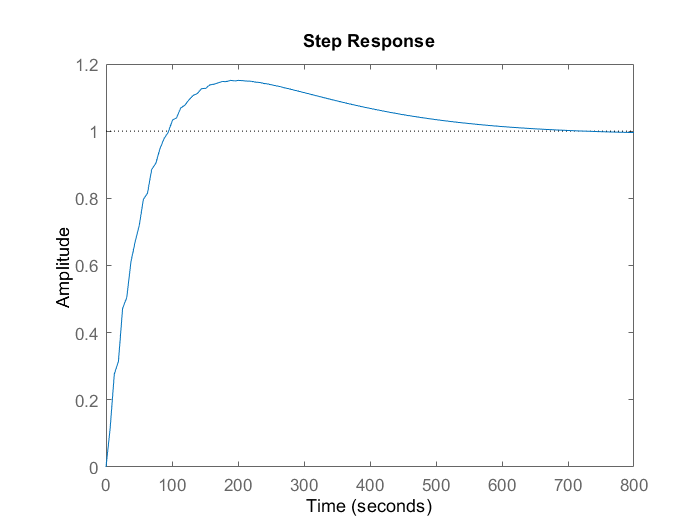

step(Gfiwithpid)

PIDforGtheta = pidtune(Gtheta,'PID')

PIDforGtheta =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 7.22, Ki = 1.06, Kd = 12.3
 
Continuous-time PID controller in parallel form.



GthetawithPID = feedback(PIDforGtheta*Gtheta,1)

GthetawithPID =
 
      12.33 s^4 + 7.839 s^3 + 3.268 s^2 + 1.136 s + 0.1586
  ------------------------------------------------------------
  5 s^5 + 12.63 s^4 + 8.739 s^3 + 3.268 s^2 + 1.136 s + 0.1586
 
Continuous-time transfer function.



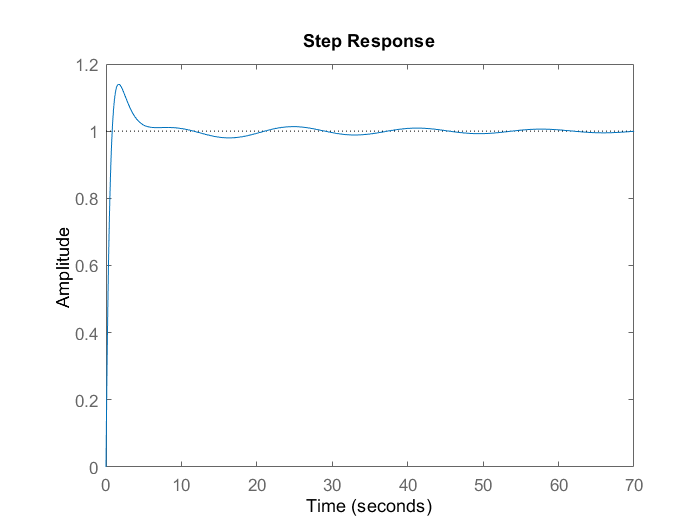

step(GthetawithPID)

## **Full-State Feedback Controller**

Controltheta = [B1 A1*B1 A1^2*B1 A1^3*B1] 

Controltheta =          0    0.2000   -0.0020   -0.0059
         0         0    0.0100    0.0294
    0.2000   -0.0020   -0.0059    0.0007
         0    0.0100    0.0294   -0.0036


det(Controltheta)

ans = -3.6000e-05

syms s a1 a2 a3 a4 Kbar1 Kbar2 Kbar3 Kbar4

Abar1 = [0 1 0 0; 0 0 1 0; 0 0 0 1; -a4 -a3 -a2 -a1];

Tdesired = det(eye(4)*s-Abar1)

$$Tdesired = s^{4}+a_{1}\,s^{3}+a_{2}\,s^{2}+a_{3}\,s+a_{4}$$

Tpolynom = det(eye(4)*s-A1)

$$Tpolynom = s^{4}+\frac{3\,s^{3}}{50}+\frac{9\,s^{2}}{50}$$

problem = coeffs(Tdesired,s,'all')==coeffs(Tpolynom,s,'all');
solution = solve(problem);
a1 =double(solution.a1)

a1 = 0.0600

a2 =double(solution.a2)

a2 = 0.1800

a3 =double(solution.a3)

a3 = 0

a4 =double(solution.a4)

a4 = 0

Abar = [0 1 0 0; 0 0 1 0; 0 0 0 1; -a4 -a3 -a2 -a1];
Bbar = [0; 0; 0; 1];
T = [Bbar Abar*Bbar (Abar^2)*Bbar (Abar^3)*Bbar]*inv(Controltheta)

T =     0.5556   32.7778         0  -11.1111
   -1.6667    1.6667         0   33.3333
    5.0000   -5.0000         0    0.0000
    0.0000         0    5.0000   -5.0000


Overshoot = 0.05; 
zeta = -log(Overshoot)/sqrt(pi^2+log(Overshoot)^2)

zeta = 0.6901

SettlingTime = 3;
Sigma = 4 /SettlingTime;
wn = Sigma/zeta

wn = 1.9321

p1 = 200;
p2 = 100;

CEdesired1 = s^4+(2*wn*zeta+p1+p2)*s^3+(2*wn*zeta*(p1+p2)+wn^2+p1*p2)*s^2+((wn^2)*(p1+p2)+2*wn*zeta*p1*p2)*s+(wn^2)*p1*p2

$$CEdesired1 = s^{4}+\frac{908\,s^{3}}{3}+\frac{178702704776425\,s^{2}}{8589934592}+\frac{3741995390033369\,s}{68719476736}+\frac{5130442052002395}{68719476736}$$

CEdesired = (s^2+2*wn*zeta*s+wn^2)*(s+p1)*(s+p2);
RootCEdesired = vpasolve(CEdesired==0,s);
p3 = double(RootCEdesired(3))

p3 = -1.3333 - 1.3983i

p4 = double(RootCEdesired(4))

p4 = -1.3333 + 1.3983i

d1 = coeffs(CEdesired,s,'all');
x1 = -d1(5);
x2 = -d1(4);
x3 = -d1(3);
x4 = -d1(2);
problem = Abar-Bbar*[Kbar1 Kbar2 Kbar3 Kbar4] == [0 1 0 0; 0 0 1 0; 0 0 0 1; x1 x2 x3 x4];
solution1 = solve(problem);
Kbar1 = double(solution1.Kbar1);
Kbar2 = double(solution1.Kbar2);
Kbar3 = double(solution1.Kbar3);
Kbar4 = double(solution1.Kbar4);
Kbar = [Kbar1 Kbar2 Kbar3 Kbar4]

Kbar = 	1.0e+04 *

    7.4658    5.4453    2.0804    0.0303


K1 = Kbar*T

K1 = 	1.0e+06 *

    0.0547    2.4339    0.0015    0.9841


ka = acker(A1,B1,[-p1 -p2 p3 p4])

ka = 	1.0e+06 *

    0.0547    2.4339    0.0015    0.9841


SSthetacl = det(eye(4)*s-A1+B1*K1)

$$SSthetacl = s^{4}+\frac{908\,s^{3}}{3}+\frac{2144432457317099933\,s^{2}}{103079215104000}+\frac{7483990780066738827\,s}{137438953472000}+\frac{410435364160191657}{5497558138880}$$

[num3 den3]=ss2tf(A1-B1*K1,B1,C1,D1);
Gthetacl = tf(num3,den3)

Gthetacl =
 
                 0.2 s^2 + 0.01 s + 0.03
  -----------------------------------------------------
  s^4 + 302.7 s^3 + 2.08e04 s^2 + 5.445e04 s + 7.466e04
 
Continuous-time transfer function.



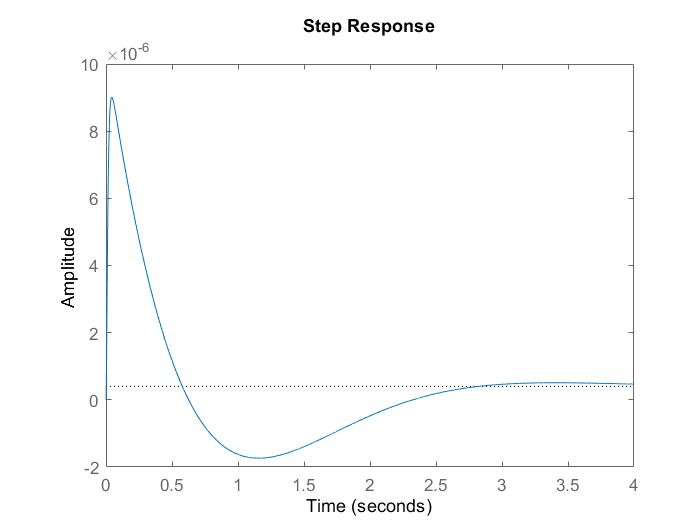

step(Gthetacl)

stepinfo(Gthetacl)

ans = struct with fields:
        RiseTime: 0.0015
    SettlingTime: 2.5511
     SettlingMin: -1.7370e-06
     SettlingMax: 9.0071e-06
       Overshoot: 2.1415e+03
      Undershoot: 432.2685
            Peak: 9.0071e-06
        PeakTime: 0.0437


[num4 den4]=ss2tf(A1-B1*K1,B1,C2,D2);
Gficl = tf(num4,den4)

Gficl =
 
                      0.01 s + 0.03
  -----------------------------------------------------
  s^4 + 302.7 s^3 + 2.08e04 s^2 + 5.445e04 s + 7.466e04
 
Continuous-time transfer function.



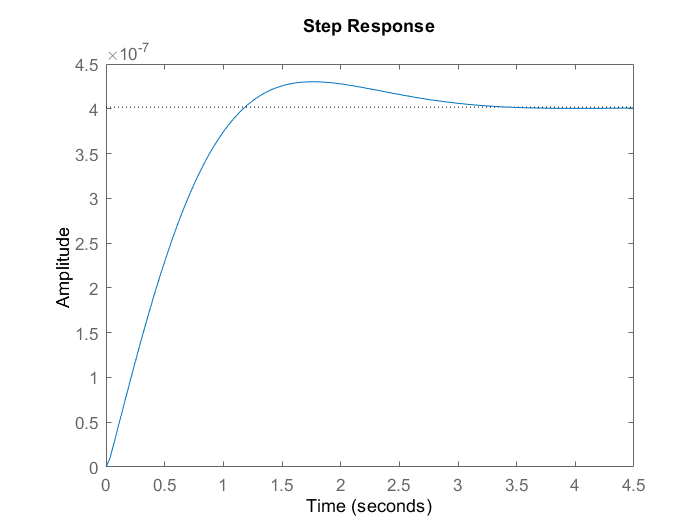

figure
step(Gficl)

stepinfo(Gficl)

ans = struct with fields:
        RiseTime: 0.8410
    SettlingTime: 2.7765
     SettlingMin: 3.6804e-07
     SettlingMax: 4.3018e-07
       Overshoot: 7.0533
      Undershoot: 0
            Peak: 4.3018e-07
        PeakTime: 1.7615


## **REFERENCES**

G. Franklin, J. Powell, and A. Emami-Naeini, Feedback Control of Dynamic Systems. Pearson, 2015.